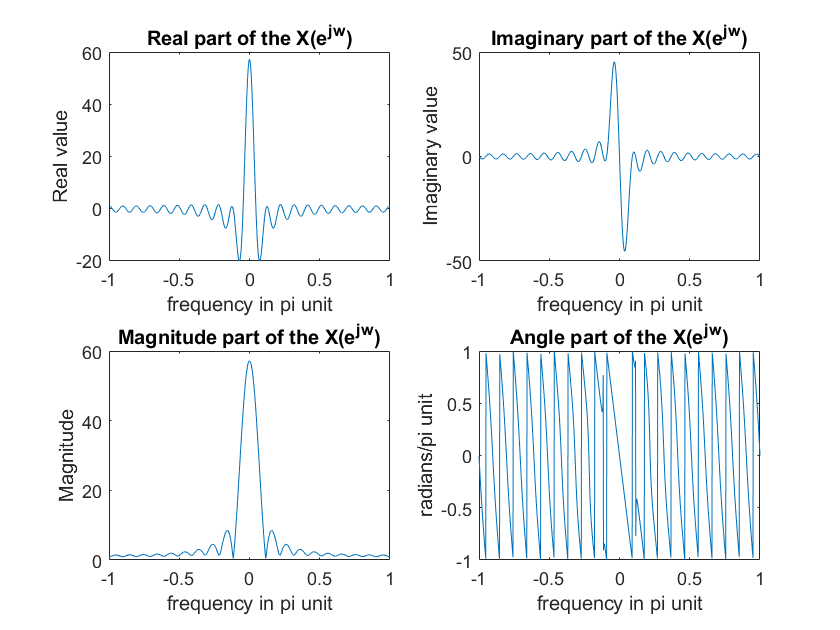

K=500;
k=-K:K;
w=(pi/K)*k;
n=-50:50;
[x1,n1]=unitseq(min(n),n(end),0);
[x2,n2]=unitseq(min(n),n(end),-21);
[x2,n2]=sigadd(x1,n1,-x2,n2);
x=n.*(0.9.^n).*x2; %max peak in 0.5 hz/pi
X=dtft(x,n,w);
dfp4(X,w)